# Worksheet 1, Part 2 / 3: Implementing Models in MATLAB

*Important Note:* Worksheet 1 comes to you in **three parts**; `worksheet1_part1.pdf`, `worksheet1_part2.mlx`, and `worksheet1_part3.mlx`

*Learning Objectives:* As a result of working through this notebook, you will learn:

- Why MATLAB is useful for working with scientific models

- How to implement stock and flow models in MATLAB

- How to apply the ideas of verification to check a model

### Required Reading

Before starting this part of the worksheet - [Matlab Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html)

- This will take about 2 hours total, so make sure to budget enough time!

For next time - read [this opinion piece](https://ensia.com/voices/science-communication/) on the ABT Framework.

### **Important Note**

You should directly edit this worksheet to complete the exercises. You will turn in this file as your submission for this part of the worksheet. Please do not print this worksheet!

clear;
help plot()

--- plot() not found. Showing help for plot instead. ---

 plot   Linear plot. 
    plot(X,Y) plots vector Y versus vector X. If X or Y is a matrix,
    then the vector is plotted versus the rows or columns of the matrix,
    whichever line up.  If X is a scalar and Y is a vector, disconnected
    line objects are created and plotted as discrete points vertically at
    X.
 
    plot(Y) plots the columns of Y versus their index.
    If Y is complex, plot(Y) is equivalent to plot(real(Y),imag(Y)).
    In all other uses of plot, the imaginary part is ignored.
 
    Various line types, plot symbols and colors may be obtained with
    plot(X,Y,S) where S is a character string made from one element
    from any or all the following 3 columns:
 
           b     blue          .     point              -     solid
           g     green       

## Reminder: Our Guiding Question

Our primary goal with this worksheet is to move towards an explanation for the following modeling question:

> “How does a single meme rise into and fall out of popularity?”

Last time you proposed a stock and flow model to help answer this question. This time we'll learn how to implement your model in MATLAB so you can easily *simulate* results from your model.

## Implementing a Model

In the previous part of the worksheet, we studied a simple model for passengers moving between two train cars:

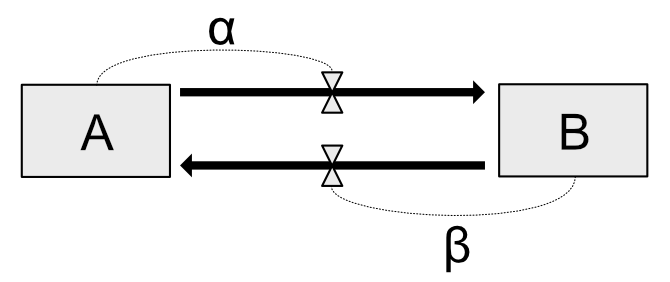

We talked about this model *qualitatively*. Now we're going to work on getting *quantitative *results from this model.

### Exercise 1 / 10

Write the stock update rule for the two-train model depicted in the stock and flow diagram above.

*Hint*: You did this in the previous part of the worksheet—this should be review!

*(Write your equations here)*

Ai+1 = Ai - aAi + bBi

Bi+1 = Bi + aAi - bBi

### Exercise 2 / 10

Compute the values $A_5, B_5$ on your own (using pen and paper, or a calculator). Use the following parameter values:


$$\alpha = 1/2 \\
\beta = 1/2 \\
A_1 = 20 \\
B_1 = 0$$


Once you have computed your calculation, enter $A_5, B_5$ below to check that your answers are correct.

% TODO: Compute values for A_5 and B_5
 A_5 = 10

A_5 = 10

 B_5 = 10

B_5 = 10


% Use the following to check your work
assert(exist('A_5'), 'You must assign your answer for A to the variable A_5')
assert(exist('B_5'), 'You must assign your answer for B to the variable B_5')
assert(A_5 + B_5 == 20, 'Your answer is incorrect')
assert(A_5 < 20, 'Your answer is incorrect')
assert(0 < B_5, 'Your answer is incorrect')
assert(A_5 == B_5, 'Your answer is incorrect')
disp('Assertions passed!')

Assertions passed!


**Important Note:** You should have found that carrying out this computation is *very tedious*. Imagine needing to do this every time you make a change to your model! We are learning Matlab so that you do not have to simulate models by hand.

### Exercise 3 / 10

Implement the train update action using MATLAB code. Assign your results to `A_2` and `B_2`.

% NOTE: Do not edit; use these parameter values
A_1 = 20;
B_1 = 0;
alpha = 1/4;
beta = 1/4;

% TODO: Implement the update action
 A_2 = A_1-alpha*A_1+beta*B_1

A_2 = 15

 B_2 = B_1+alpha*A_1-beta*B_1

B_2 = 5


% NOTE: Do not edit this; use this to check your work
assert(A_2 == 15, 'Your answer is incorrect')
assert(B_2 == 5, 'Your answer is incorrect')
disp('Assertions passed!')

Assertions passed!


We can also implement code in a *function*. This allows us to re-use code more easily. A function takes some number of inputs (sometimes called *arguments*), and provides some number of outputs (sometimes called *return values*). For instance, the following code would define a function named `example_function` with two inputs and two outputs.

% NOTE: No need to edit this code; this is just an example
% function [output_1, output_2] = example_function(input_1, input_2)
%     % Do some calculations
%     output_1 = input_1 + input_2;
%     output_2 = input_1 - input_2;
% end

I implemented the train update action as a function `action_trains()` with the following code:

% NOTE: No need to edit this code; this is at the bottom of this LiveScript
% function [a_new, b_new] = action_trains(a_old, b_old, alpha, beta)
%     a_to_b = a_old * alpha;
%     b_to_a = b_old * beta;
% 
%     a_new = a_old - a_to_b + b_to_a;
%     b_new = b_old + a_to_b - b_to_a;
% end

*Aside:* Due to technical limitations, MATLAB does not allow for function definitions in the middle of a script. Therefore, all function definitions in this LiveScript are at the bottom of the file.

You'll practice using functions in the next exercise.

### Exercise 4 / 10

Use the action function to compute $A_3, B_3$ from $A_2, B_2$.

*Hint:* The function signature for `action_trains` is:

`    [a_new, b_new] = action_trains(a_old, b_old, alpha, beta)`

Note that this is a function with multiple return values `a_new` and `b_new`. You will need to use the square bracket notation shown above `[a_new, b_new] = ...` to "capture" both outputs from the function. Use this information to help complete this exercise.

% TODO: Use the action function action_trains() to assign values
% to A_3 and B_3
[A_3,B_3]=action_trains(A_2,B_2,alpha,beta)

A_3 = 12.5000

B_3 = 7.5000

% NOTE: Do not edit this; use this to check your work
assert(A_3 == 12.5, 'Your answer is incorrect')
assert(B_3 == 7.5, 'Your answer is incorrect')
disp('Assertions passed!')

Assertions passed!


In the MATLAB Onramp, you learned about how to use `for` loops to repeat an action multiple times. You'll use this idea to run the update action multiple times.

### Exercise 5 / 10

Write a `for` loop to compute $A_5, B_5$ from $A_1, B_1$. Answer the questions below.

*Hint 1:* Remember that you can access the entries of a vector by using parentheses. For instance, the 2nd entry of `A` would be `A(2)`.

*Hint 2:* You can use vector indexing with multiple return values! This would look like `[A(i+1), B(i+1)] = ...`

% NOTE: Do not edit; use these parameter values
A_1 = 20;
B_1 = 0;
alpha = 1/2;
beta = 1/2;

% NOTE: Do not edit; use this to store the simulation results
T = 1:5;
A = zeros(5, 1); A(1) = A_1;
B = zeros(5, 1); B(1) = B_1;

% TODO: Write a `for` loop to run the update function the appropriate
% number of times
for i = 1:4
    [A(i+1),B(i+1)] = action_trains(A(i),B(i),alpha,beta)
end

A =     20
    10
     0
     0
     0


B =      0
    10
     0
     0
     0


A =     20
    10
    10
     0
     0


B =      0
    10
    10
     0
     0


A =     20
    10
    10
    10
     0


B =      0
    10
    10
    10
     0


A =     20
    10
    10
    10
    10


B =      0
    10
    10
    10
    10


% NOTE: Do not edit; use this to check your work
assert(length(A) == 5, 'Your results are the wrong size')
assert(length(B) == 5, 'Your results are the wrong size')
disp('Assertions passed!')

Assertions passed!


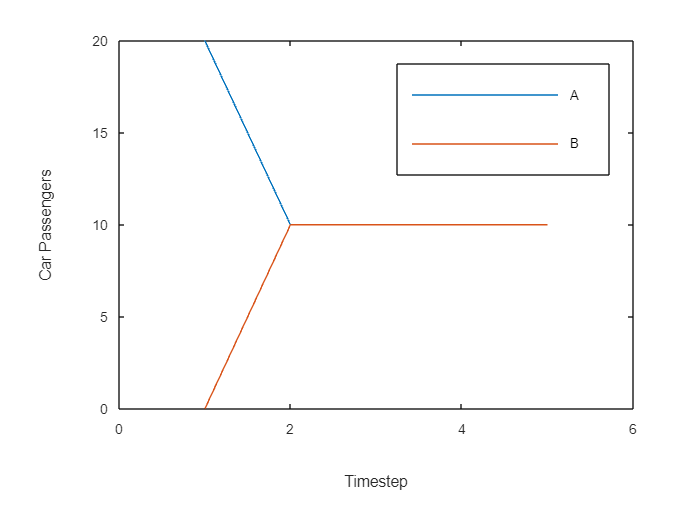


figure()
plot(T, A, 'DisplayName', 'A'); hold on;
plot(T, B, 'DisplayName', 'B')
xlabel('Timestep')
ylabel('Car Passengers')
legend()

- Does this result agree with the results that you hand-calculated above?

-  *(Write your response here)*

- Yes, the result was 10 just like my calculations.

The advantage of writing MATLAB code is that we can easily *re-use* code to try a simulation with different parameter values. You'll do this in the next exercise.

### Exercise 6 / 10

Write all of the code necessary to simulate the trains model up to timestep 10. Answer the questions below.

*Hint:* You can (and should!) copy code from the previous Exercise to help complete this task. However, you will need to *adapt* the code to complete the exercise!

% NOTE: Do not edit; use these parameter values
A_1 = 20;
B_1 = 0;
alpha = 2/6;
beta = 1/6;

% TODO: Write *all* of the code necessary to simulate the model up to 
% A_10, B_10 using the parameters above. Assign the result vectors 
% to the variables A and B
T = 1:10;
A = zeros(10, 1); A(1) = A_1;
B = zeros(10, 1); B(1) = B_1;
for i = 1:9
    [A(i+1),B(i+1)] = action_trains(A(i),B(i),alpha,beta)
end

A =    20.0000
   13.3333
         0
         0
         0
         0
         0
         0
         0
         0


B =          0
    6.6667
         0
         0
         0
         0
         0
         0
         0
         0


A =    20.0000
   13.3333
   10.0000
         0
         0
         0
         0
         0
         0
         0


B =          0
    6.6667
   10.0000
         0
         0
         0
         0
         0
         0
         0


A =    20.0000
   13.3333
   10.0000
    8.3333
         0
         0
         0
         0
         0
         0


B =          0
    6.6667
   10.0000
   11.6667
         0
         0
         0
         0
         0
         0


A =    20.0000
   13.3333
   10.0000
    8.3333
    7.5000
         0
         0
         0
         0
         0


B =          0
    6.6667
   10.0000
   11.6667
   12.5000
         0
         0
         0
         0
         0


A =    20.0000
   13.3333
   10.0000
    8.3333
    7.5000
    7.0833
         0
         0
         0
         0


B =          0
    6.6667
   10.0000
   11.6667
   12.5000
   12.9167
         0
         0
         0
         0


A =    20.0000
   13.3333
   10.0000
    8.3333
    7.5000
    7.0833
    6.8750
         0
         0
         0


B =          0
    6.6667
   10.0000
   11.6667
   12.5000
   12.9167
   13.1250
         0
         0
         0


A =    20.0000
   13.3333
   10.0000
    8.3333
    7.5000
    7.0833
    6.8750
    6.7708
         0
         0


B =          0
    6.6667
   10.0000
   11.6667
   12.5000
   12.9167
   13.1250
   13.2292
         0
         0


A =    20.0000
   13.3333
   10.0000
    8.3333
    7.5000
    7.0833
    6.8750
    6.7708
    6.7188
         0


B =          0
    6.6667
   10.0000
   11.6667
   12.5000
   12.9167
   13.1250
   13.2292
   13.2812
         0


A =    20.0000
   13.3333
   10.0000
    8.3333
    7.5000
    7.0833
    6.8750
    6.7708
    6.7188
    6.6927


B =          0
    6.6667
   10.0000
   11.6667
   12.5000
   12.9167
   13.1250
   13.2292
   13.2812
   13.3073


% NOTE: Do not edit; use this to check your work
assert(length(T) == 10, 'Your time vector is the wrong size')
assert(length(A) == 10, 'Your results are the wrong size')
assert(length(B) == 10, 'Your results are the wrong size')
assert(abs(A(end) - 6.6927) < 1e-4, 'Your end value A(end) is wrong')
assert(abs(B(end) - 13.3073) < 1e-4, 'Your end value B(end) is wrong')
disp('Assertions passed!')

Assertions passed!


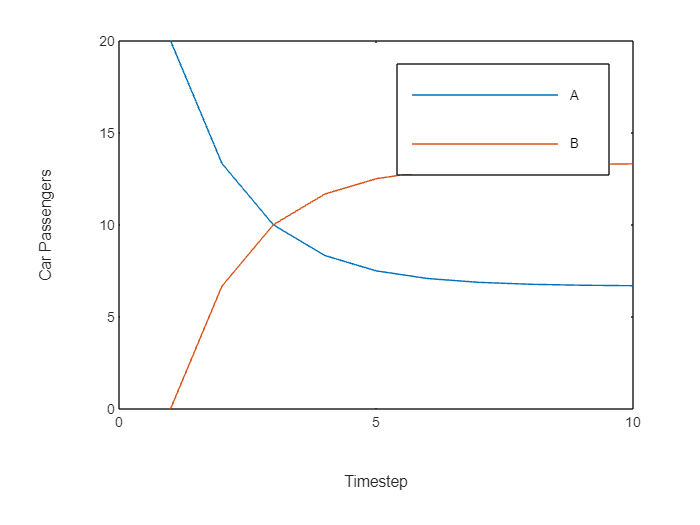


figure()
plot(T, A, 'DisplayName', 'A'); hold on;
plot(T, B, 'DisplayName', 'B')
xlabel('Timestep')
ylabel('Car Passengers')
legend()

- Do the trains end up with the same number of passengers at the end of the simulation?

-  *(Write your response here)*

- Explain the observation you made for the previous question in terms of the model parameters $\alpha, \beta$.

-  *(Write your response here)*

### Using the Workspace

Find the **Workspace** tab in your MATLAB window and click on it. (It should look something like the following.)

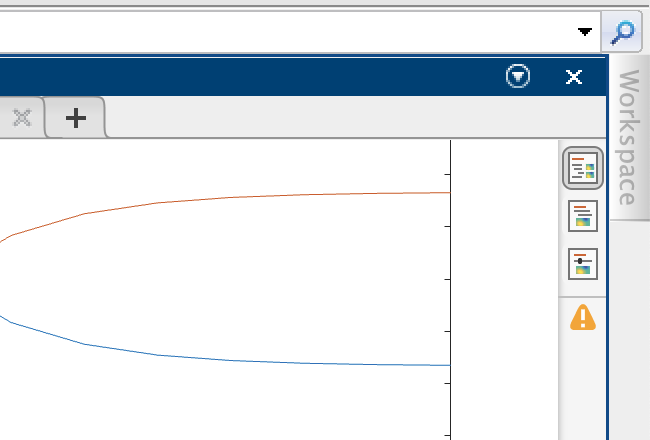

Once you click on Workspace, it should open a bar like the following:

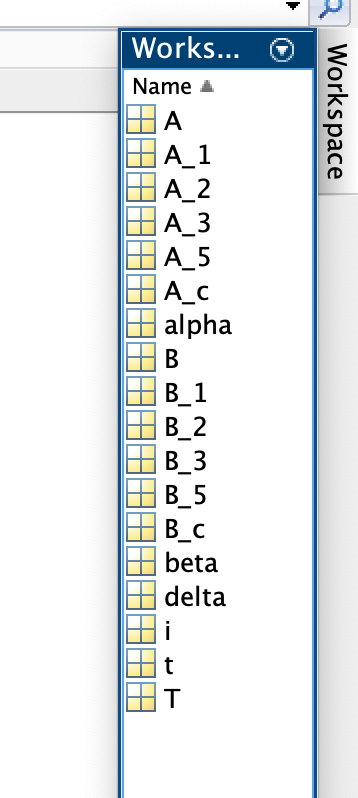

This view is too narrow; it doesn't show the values of the variables. You can click and drag to resize the Workspace so you can see the values.

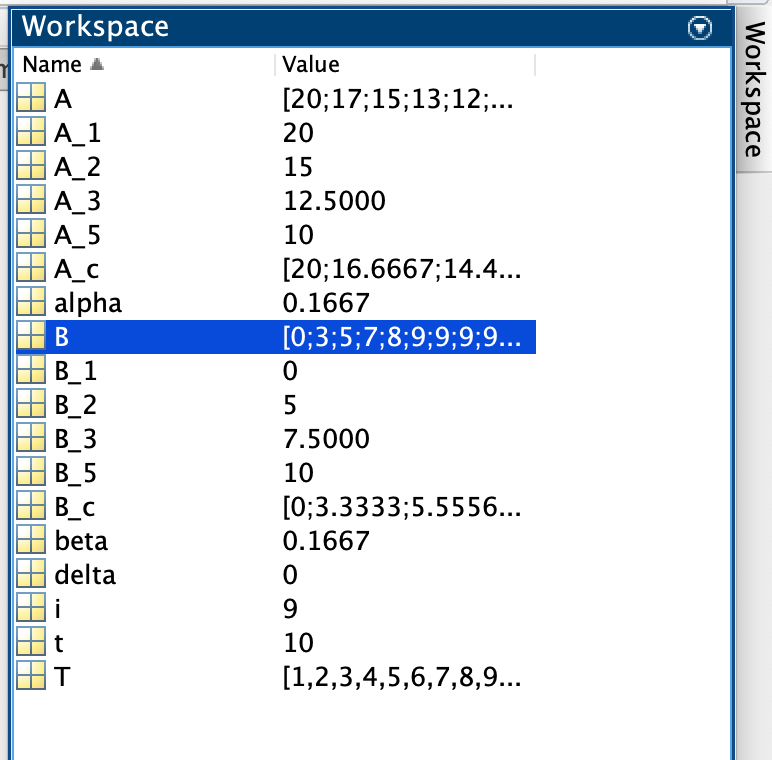

The Workspace allows you to inspect all of the variables that MATLAB has in memory. You'll practice using the Workspace in the next exercise.

### Exercise 7 / 10

Use the workspace to answer the following questions:

- How long is the vector `A`?

- *    (Write your response here.) *10x1

- Is `A_1` a vector or scalar?

- *    (Write your response here.) *A scalar

- What is the current value of `beta`? 

- *    (Write your response here.) *0.1667

## Iterating On A Model

We *never* expect the model to be perfect the first time we hit `Run`. In fact, professional computational scientists have several strategies for systematically finding and eliminating problems with computational models. Central to this approach are the processes of *verification* and *validation*. We'll cover validation in Worksheet 2. Up next, we'll practice applying verification to the trains model.

### Verification

In the reading we learned about *verification*. The definition of verification is:

> The process of determining that a model implementation accurately represents the developer’s conceptual description of the model and the solution to the model.

Verification is a multi-step process: We should first determine a set of verification "facts" that should be true about results from the model. We then test that these facts are true about our model's results.

Verification facts should be non-obvious, emergent properties of the model. Facts like "the model runs" are completely useless. Other facts like "the parameters are the correct values" are important things to check, but are not verification facts. More useful facts are properties that remain constant as the model runs. For instance, for the train model, we would expect all of the following to be true:

- Non-negative people counts $A_i \geq 0$, $B_i \geq 0$ for all $i = 1, 2, \dots$

- Total number of passengers constant $A_i + B_i = N = \text{const.}$ for all $i = 1, 2, \dots$ 

- Total never exceeded $A_i \leq N, B_i \leq N$ for all $i = 1, 2, \dots$

### Exercise 8 / 10

Run and inspect the following code. Answer the questions below.

% NOTE: Do not edit this code; run and inspect
A_1 = 20;
B_1 = 0;
alpha = 2/6;
beta = 1/6;

t = 10;
T = 1:t;
A = zeros(t, 1); A(1) = A_1;
B = zeros(t, 1); B(1) = B_1;

for i = 1:(t-1)
    A(i+1) = - alpha * A(i) + beta * B(i);
    B(i+1) = + alpha * A(i) - beta * B(i);
end

A

A =    20.0000
   -6.6667
    3.3333
   -1.6667
    0.8333
   -0.4167
    0.2083
   -0.1042
    0.0521
   -0.0260


B

B =          0
    6.6667
   -3.3333
    1.6667
   -0.8333
    0.4167
   -0.2083
    0.1042
   -0.0521
    0.0260


- The stocks A and B track the number of people on two train cars. Do the values in the vectors `A` and `B` make sense, given that these represent counts? Why or why not?

-  *(Write your response here) *No because sometimes they're negative and you can't have a negative number of people on a train.

- The model does not have any sources or sinks. Physically, this means the only place that people in the model can be is on one of the two train cars. What does this mean about the *sum* of `A` and `B`? Do the model results respect this sum?

-  *(Write your response here)* This means A and B have to be equal to the total number of people on the train car. The model results do not respect this sum because if you add up the last value in each vector it does not add to the total number of people in the train.

- There is a mistake in the model implementation above. What is the mistake? Why did this result in the issues you documented above?

-  *(Write your response here) *The mistake is that the inital value of A and B at i is not added to the equation. This means that only the people that moved are accounted for with no people to replace them. It also adds a negative to A that doesn't need to be there, hence the negative numbers.

### Model Error or Abstraction?

Hopefully, you noticed that the models above return *fractional* values for the number of passengers. This is strange: We can't have fractional people! At first, it may seem like our model is *invalid.* However, that is not necessarily the case! You'll investigate this more closely in the next exercise.

### Exercise 9 / 10

Run the following code, adjust the `alpha` and `beta` parameters, and answer the questions below.

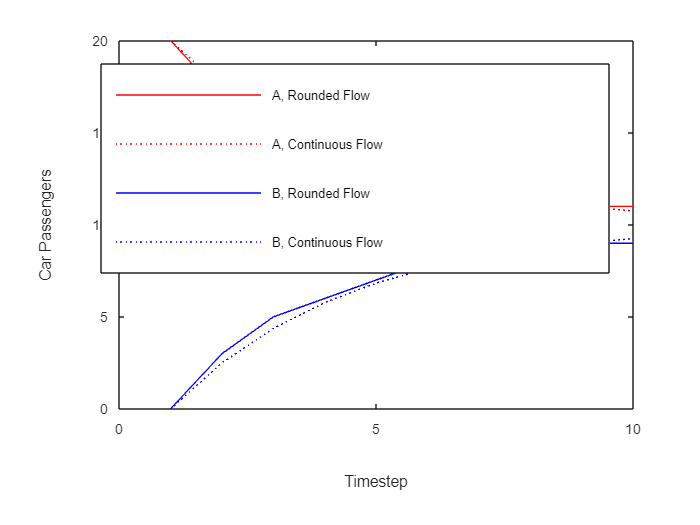

% TODO: Modify the alpha and beta parameters to help answer the questions
% below
alpha = 1/8;
beta = 1/8;

% NOTE: Do not edit; use these parameter values
A_1 = 20;
B_1 = 0;

% NOTE: Do not edit this code; use this to run the simulation
t = 10;
T = 1:t;
A = zeros(t, 1); A(1) = A_1;
B = zeros(t, 1); B(1) = B_1;
A_c = zeros(t, 1); A_c(1) = A_1;
B_c = zeros(t, 1); B_c(1) = B_1;

for i = 1:(t-1)
    % Rounded flows
    delta = round(alpha * A(i) - beta * (B(i)));
    A(i+1) = A(i) - delta;
    B(i+1) = B(i) + delta;

    % Continuous flows
    [A_c(i+1), B_c(i+1)] = action_trains(A_c(i), B_c(i), alpha, beta);
end

figure()
plot(T, A, 'r', 'DisplayName', 'A, Rounded Flow'); hold on;
plot(T, A_c, 'r:', 'DisplayName', 'A, Continuous Flow');
plot(T, B, 'b', 'DisplayName', 'B, Rounded Flow')
plot(T, B_c, 'b:', 'DisplayName', 'B, Continuous Flow');
xlabel('Timestep')
ylabel('Car Passengers')
legend()

- Compare the behavior of the Rounded and Continuous Flow models. What is similar? What is different?

-  *(Write your similarities here) *They both either increase or decrease exponentially

- *    (Write your differences here) *The Continuous Flow models keep increasing/decreasing throughout the whole graph while the Rounded models stop at a certain point.

- Test smaller values of $\alpha, \beta$. Is there a "minimum" value that works with the Rounded Flow model?

- *    (Write your response here) *Yes, 1/7

- How might we interpret a fractional number of people on car A or B?

- *    (Write your response here) *People are traveling inbetween cars.

## Meme Game Application

Now that you've learned how to implement stock and flow models in MATLAB, let's apply those ideas to help understand the meme game. First, let's remind ourselves of our guiding question for this modeling effort:

> “How does a single meme rise into and fall out of popularity?”

Your goal is to develop a stock and flow model that can exhibit this "rise and fall" behavior. The following exercises will scaffold this modeling effort.

### Exercise 10 / 10

In the previous part of the worksheet (last class), you developed a stock and flow model to represent the meme game. Implement your model in MATLAB below.

*Note:* You might not finish this in-class today. Make sure to finish this tonight before you turn this part of the worksheet in.

*Hint:* You might find it helpful to copy some of the code you used above to get yourself started.

 Likeit = 0

Likeit = 0

 indifferent = 107

indifferent = 107

 Dontlikeit = 0

Dontlikeit = 0

 for i = 1:24
     num = randi([1,50],1,1)
     if num > 40
         if Likeit<107
             Likeit = Likeit+1
         end
     elseif num > 10||num < 40
             if num < 25 && Likeit > 0
                 Likeit = Likeit - 1
                 if indifferent < 107
                    indifferent = indifferent + 1;
                 end
             end
     elseif num < 10
             if Dontlikeit < 107
                 Dontlikeit = Dontlikeit + 1
                 indifferent = indifferent - 1
             end
     end
    
 end

num = 21

num = 4

num = 12

num = 7

num = 10

num = 12

num = 21

num = 3

num = 46

Likeit = 1

num = 48

Likeit = 2

num = 25

num = 25

num = 17

Likeit = 1

num = 46

Likeit = 2

num = 19

Likeit = 1

num = 6

Likeit = 0

num = 40

num = 20

num = 13

num = 21

num = 5

num = 7

num = 48

Likeit = 1

num = 48

Likeit = 2

## Submission Checklist

Follow these steps to submit your work!

- Click the `Run` button to make sure your worksheet executes properly. Try to fix any errors before submission.

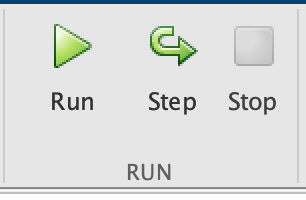

- Convert your worksheet to a PDF, as shown in the following screengrab

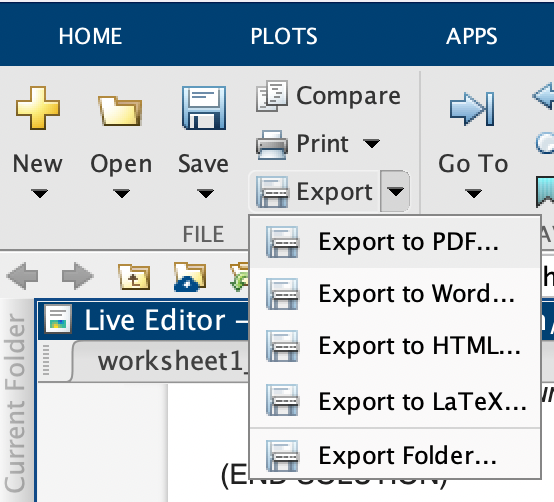

- Upload your PDF to Canvas!

## Helper Functions

These functions are used throughout this Live Script.

function [a_new, b_new] = action_trains(a_old, b_old, alpha, beta)
    % Update the state of the trains model
    %
    % Usage
    %   [a_new, b_new] = action_trains(a_old, b_old, alpha, beta)
    %
    % Inputs
    %   a_old (float): Previous value of A stock
    %   b_old (float): Previous value of B stock
    %   alpha (float): Flow out of Car A parameter
    %   beta (float): Flow out of Car B parameter
    %
    % Returns
    %   a_new (float): New value of A stock
    %   b_new (float): New value of B stock
    %
    a_to_b = a_old * alpha;
    b_to_a = b_old * beta;

    a_new = a_old - a_to_b + b_to_a;
    b_new = b_old + a_to_b - b_to_a;
end